clear all
close all
clc
load ide_modelli_scara.mat

Gs1 = modello_continuo_q1;
tf(Gs1);
wn = 665;
xci_z=0.15; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
F = 1/(0.003*s+1)

F =
 
       1
  -----------
  0.003 s + 1
 
Continuous-time transfer function.
Model Properties


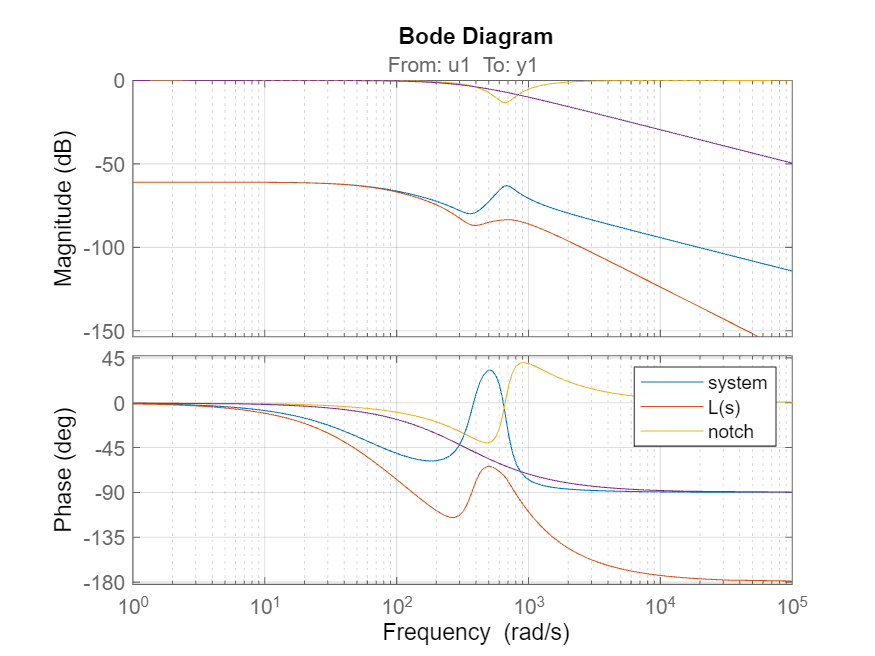

P=Gs1*notch*F;

bode(Gs1)
hold on
bode(P)
bode(notch)
bode(F)
hold off

grid on
legend('system','L(s)','notch')

wc = 150;
Kp=1/abs(freqresp(P,wc));

C=Kp

C = 3.4206e+03

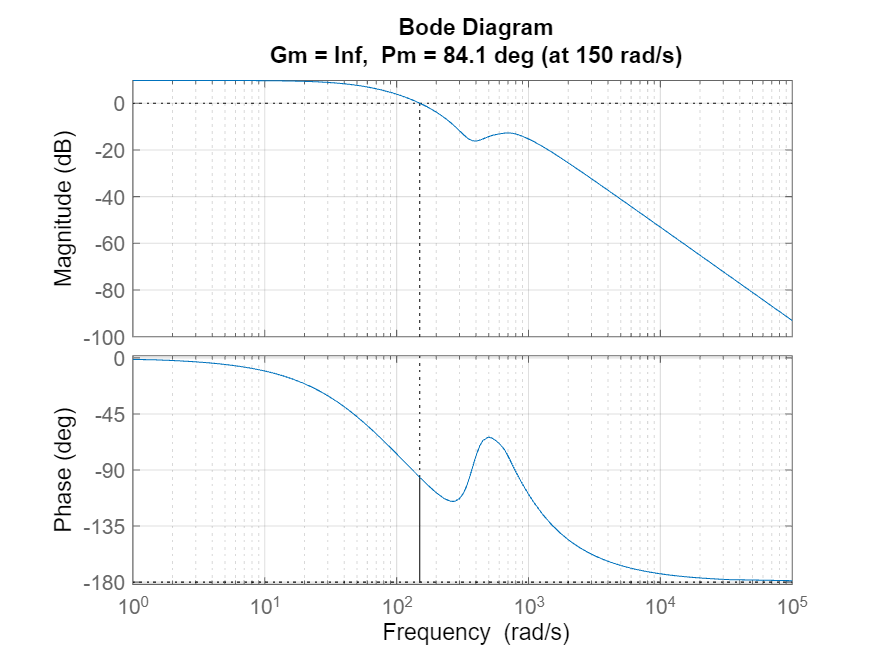

wtest =    100
   101
   102
   103
   104
   105
   106
   107
   108
   109


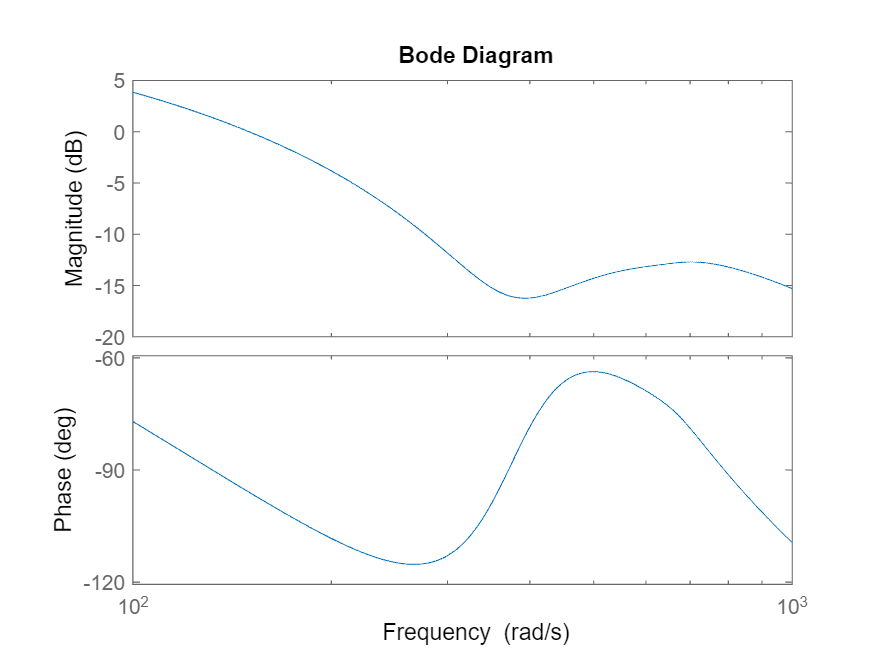

Error using DynamicSystem/bode
"Linewidth" is not a valid plot style.

figure
margin(C*P)


tf(loop1)
l1_1 = tf(1/loop1)

G1 = loop1*1/s;
bode(G1)
% tf(G1)


% wc_des=200;
% J=@(x)pivel_cost_function(x,G1,wc_des);
% MS=1.4;
% wh=2000;
% Fh_max=0.1;
% wl=0.1;
% Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
% 
% w_vector=logspace(-3,3)'; % [10^-3,10^3]
% w_vector=sort([w_vector;wl;wh]);

%nlcon=@(x)pivel_constraints(x,G1,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

%x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
%x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon)
%Kp=x(1);
%Ki=x(2);
%C1=tf([Kp Ki],[1 0])
%margin(C1*G1)
%step(feedback(C1*G1,1))